# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
sceneLuminance = 1000;
numRays = 128;
filmResolution = 1024;

sceneChoice = "Chess Set";

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance); %, ...

Read 9 materials and 3 textures..


    %'lensFile','dgauss.22deg.3.0mm.json');
pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, ...
    'sceneLuminance', sceneLuminance);

Read 9 materials and 3 textures..


% match to sensor size, should be a formula
pinholeCPScene.thisR.set('fov', 30);

% room light might be throwing off AE
%pbrtCPScene.thisR.set('skymap','room.exr','rotation val',[90, -90, 0]);
lightName = 'from camera';
ourLight = piLightCreate(lightName,...
                        'type','distant',...
                        'cameracoordinate', true);
pbrtCPScene.thisR.set('lights', ourLight,'add');
pinholeCPScene.thisR.set('lights', ourLight, 'add');

%pinholeCPScene.thisR.set('focaldistance', '.005');

if strcmp(sceneName, "cornell_box")
    bunny = piAssetLoad('bunny.mat');
    bunny.name = 'Bunny';
    pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, bunny.thisR);
    pbrtCPScene.thisR.set('asset', 'Bunny_B', 'world position',...
        [0 0 1.3]);    % in case bunny is out of our frame
    
    %if you want object motion
    pbrtCPScene.objectMotion = {{'Bunny_B', [0 .01 0], []}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', 'Bunny_B', 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    %mcc = piAssetLoad('macbeth.mat');
    %pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, mcc.thisR);
    %pbrtCPScene.thisR.set('material', 'add', mcc.thisR.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    %[~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    %pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, coord.thisR);
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
ourSensor = sensorCreate('imx363'); 
ourSensor = sensorSet(ourSensor, 'size', [1024, 1280]);
pinholeSensor = sensorCreate('imx363'); 
pinholeSensor = sensorSet(pinholeSensor, 'size', [1024, 1280]);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', ourSensor); 

% try to make the pinhole a pinhole:)
% if it works, should integrate into cpCamera
pinholeCamera = cpBurstCamera();
pinholeCamera.cmodules(1) = cpCModule('sensor', pinholeSensor);
pinholeCamera.cmodules(1).oi.optics = opticsSet(pinholeCamera.cmodules(1).oi.optics,'fnumber',8);

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

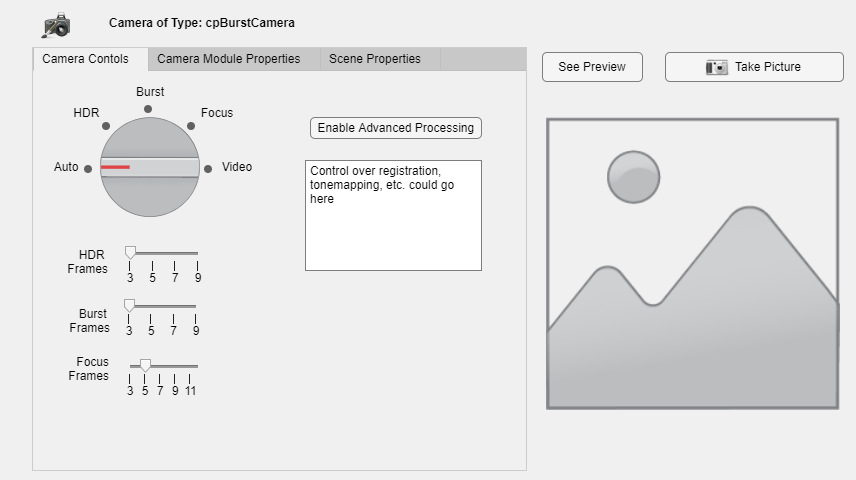

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

Using single-image Auto, multi-image Burst and Focus Stacked.

Elapsed time is 1.775220 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  20.92
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.51
*** Rendering time for ChessSet:  23.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done. Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d

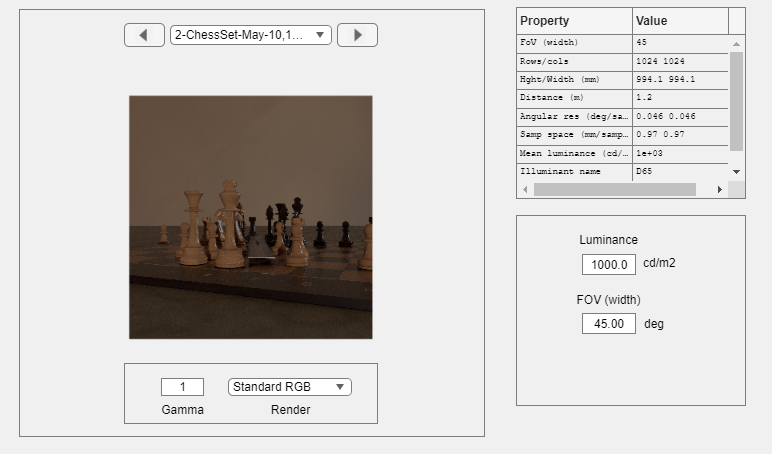

% baseline test
autoCamera = cpCamera();
autoImage = autoCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1);

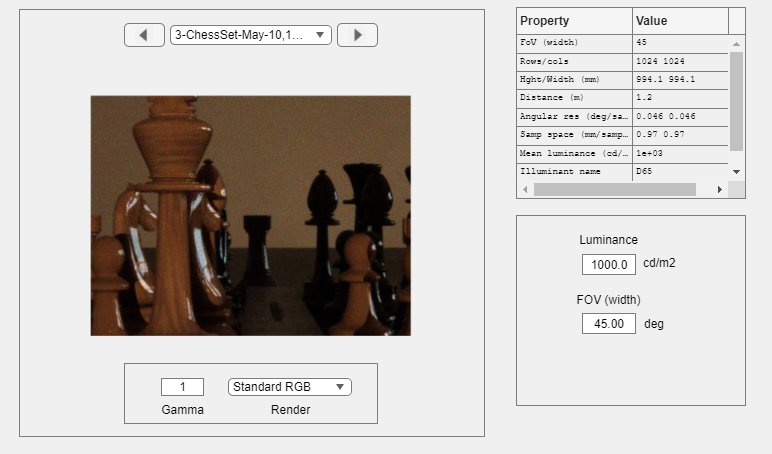

Elapsed time is 1.754031 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  20.95
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.84
*** Rendering time for ChessSet:  24.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.18
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  21.09
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.62
*** Rendering time for ChessSet:  24.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 1.745537 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.26
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d

imshow(autoImage);

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

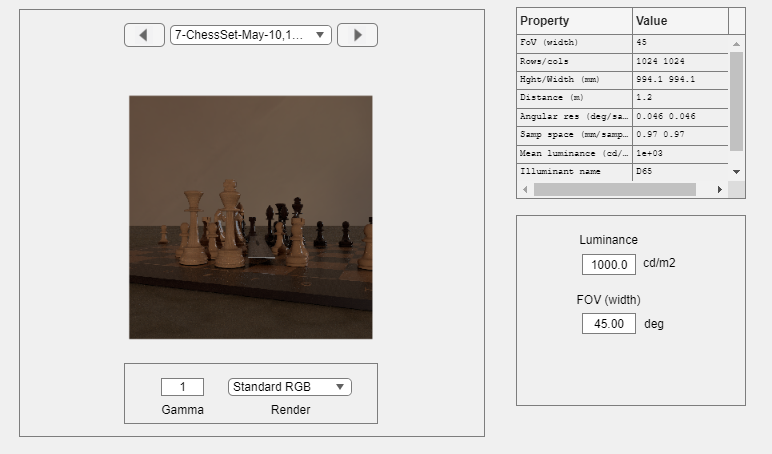

Elapsed time is 1.739677 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  21.04
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.63
*** Rendering time for ChessSet:  24.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  21.08
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.42
*** Rendering time for ChessSet:  23.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 1.735549 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.27
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d

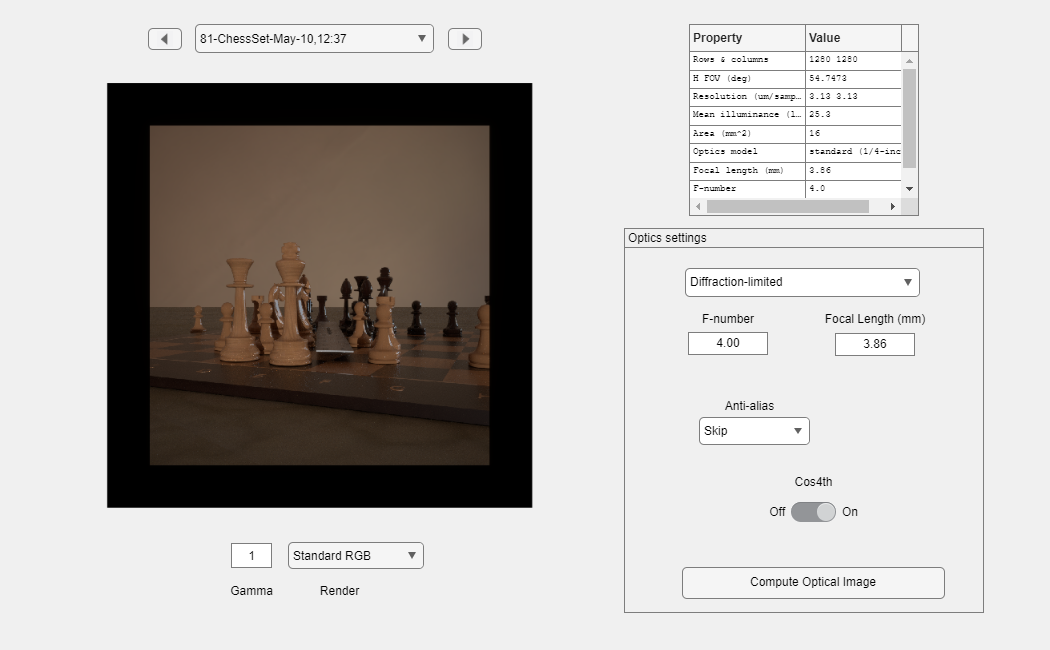

Fmeasure     
SMeasure[100%]
Weights [100%]
Fusion [100%]

Elapsed time: 1.11 s:
Reading  (45.0%).
Fmeasure (38.2%).
SMeasure (6.7%).
Fusion   (10.1%).



stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 9, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

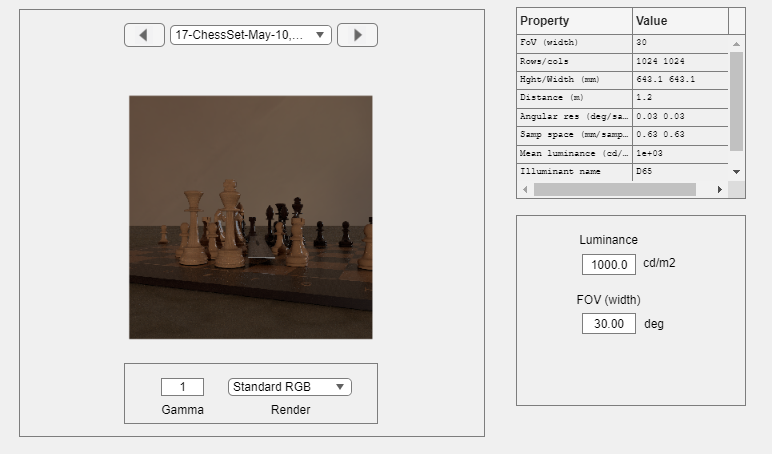

Elapsed time is 1.736047 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.28
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  22.76
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.73
*** Rendering time for ChessSet:  25.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.27
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  20.90
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.82
*** Rendering time for ChessSet:  24.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 1.739867 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.18
Render: docker --context render-vista exec -i  pbrt-gpu-Windows11575 sh -c "cd /iset/iset3d

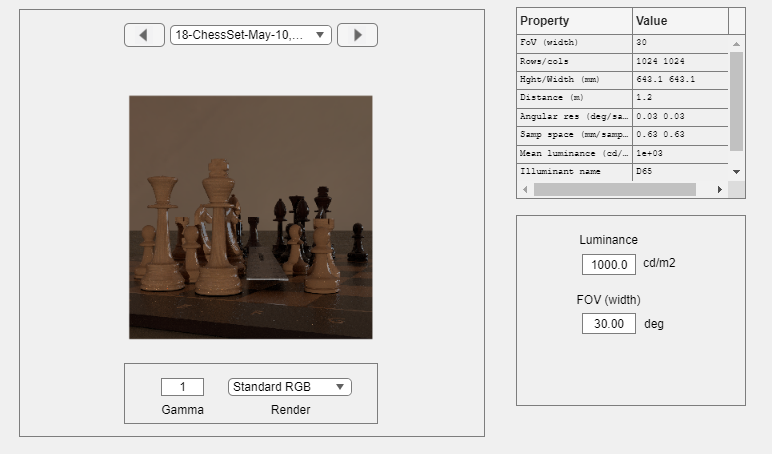


pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

Burst vs. Stacked with no motion

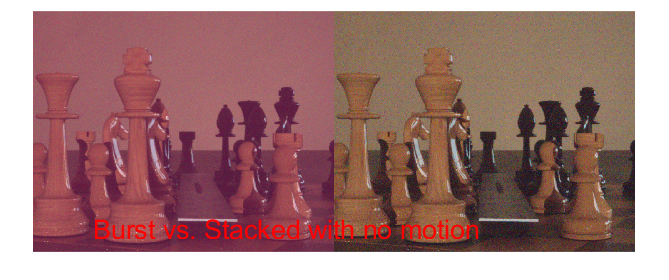


cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');

Pinhole vs. Stacked with no motion

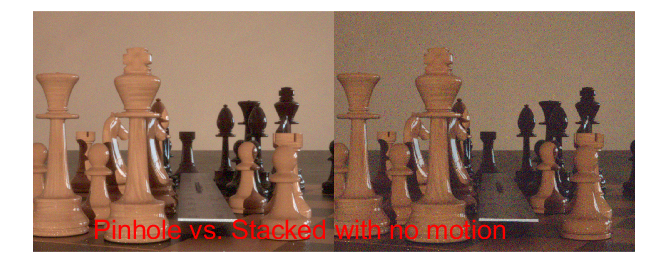

cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');

Pinhole vs. Burst with no motion

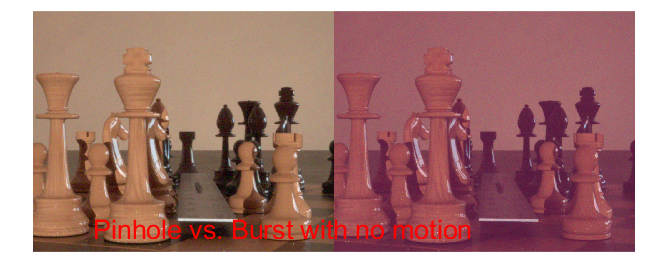

cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation NVIDIA GeForce RTX 3090/PCIe/SSE2with driver version: 4.6.0 NVIDIA 510.06


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 13838.6719 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 3302.6813 total seconds.
